clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 1/16*25.4 %mm

diameter =        1.5875


height = 1/32*25.4 %mm

height =       0.79375


Br_max = 14800*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;

% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02072024_D101N52_test2\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Adjust the location for the magnet
loc = location + [0, 0, 16];

01312024

calculate magnetic field strengths of other magnets - find combination with largets magnetic field strength 

Redo measurements closer to sensor (maybe try n52 right away)

Use smallest magnet "reasonably" detecable at 2 cm. (just measure all of them at 2cm)

    Use strongest magnet, play with z-distance, decreae

Try fitting with center 4 sensors only

% Create a cell array to store all rows
all_sen = cell(length(data_matrix), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(data_matrix)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[ 0.028635 -0.01152 -0.024829]}    {[  0.02586 -0.01665 -0.054426]}    {[  0.008235 -0.02394 -0.067107]}    {[  -0.02097 -0.02004 -0.059919]}    {[  0.03114 0.003045 -0.025797]}    {[   0.03183 0.00435 -0.056483]}    {[  0.007395 0.004275 -0.082449]}    {[  -0.023985 0.00741 -0.070011]}    {[  0.026265 0.01494 -0.02149]}    {[ 0.022035 0.02526 -0.038405]}    {[   0.00528 0.03027 -0.059605]}    {[  -0.02073 0.02847 -0.048957]}    {[0.017235 0.017565 -0.013262]}    {[ 0.01509 0.025815 -0.022627]}    {[ 0.003975 0.03417 -0.029234]}    {[-0.010995 0.029955 -0.027515]}
    {[   0.02853 -0.0132 -0.023159]}    {[  0.025905 -0.0228 -0.048013]}    {[   0.00987 -0.02862 -0.061686]}    {[ -0.01716 -0.025395 -0.055854]}    {[ 0.03102 -0.000135 -0.025216]}    {[ 0.035055 -0.00072 -0.059677]}    {[ 0.009225 -0.002625 -0.085837]}    {[   -0.02427 0.00018 -0.070906]}    {[  0.02913 0.01167 -0.023547]}    {[ 0.02634 0.022695 -0.045327]}    {[  0.007395 0.02751 -0.068873]

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =      0.070015    -0.008979     -0.87249
    -0.042195     0.071434     -0.88872
    -0.099098    -0.017318     -0.82771
     -0.14571     0.013489     -0.86443
     -0.18944    0.0029222     -0.83477
     -0.18217     0.043963     -0.85004
      0.14435    -0.033632     -0.83684
     0.038711    -0.029219     -0.88173
  -8.2433e-05    -0.047407     -0.79812
   -0.0044373    -0.069767     -0.79785


multiloc = multipreds(:,4:6)

multiloc =       -3.6575       -3.076       15.861
      -3.0824      -2.5052       15.865
      -2.7053     -0.93242       15.542
      -2.4651    -0.032974       15.792
      -2.1932      0.88123       15.643
      -2.4472        1.748       15.706
      -3.2095      -2.9112       15.731
      -2.5335      -1.9368       15.831
       -2.251     -0.78759       15.362
      -2.3684      0.36821       15.317


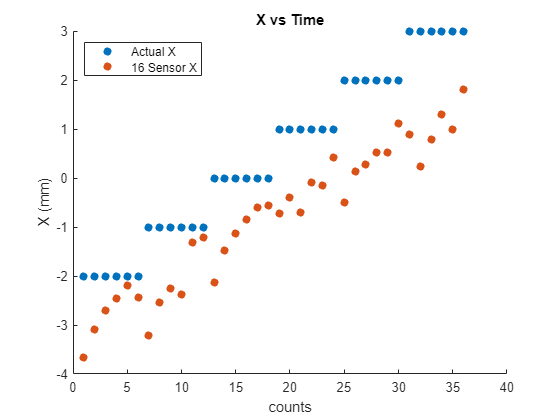

scatter(1:length(multiloc),loc(:,1), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

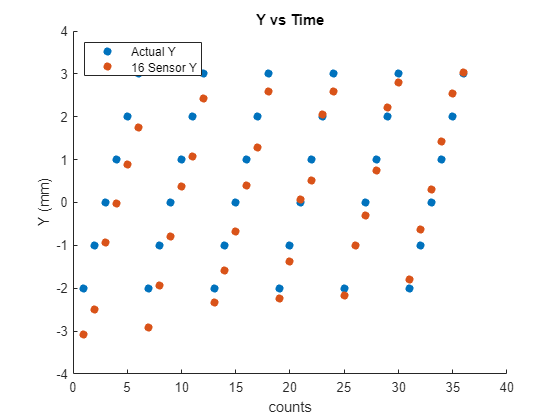

scatter(1:length(multiloc),loc(:,2), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%lim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((multiloc-r0).^2, 2));

r02 = [location(1,1) location(1,2) location(1,3)];
zi2 = sqrt(sum((location-r02).^2, 2));

SSR = sum((zi2 - testx).^2)

SSR =        19.214


SST = sum((zi2 - mean(testx)).^2)

SST =        109.44


R2 = 1 - SSR/SST

R2 =       0.82443


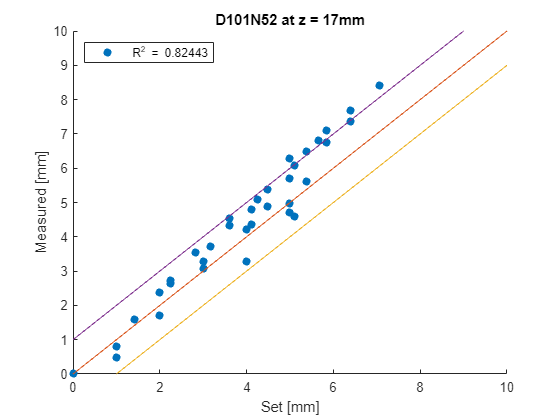


scatter(zi2, testx, 'filled')
hold on;
plot(0:10, 0:10)
plot(0:10, -1:9)
plot(0:10, 1:11)
ylim([0 10])
xlabel("Set [mm]")
ylabel('Measured [mm]')
title('D101N52 at z = 17mm')
legend(['R^2 = ', num2str(R2)], Location = 'northwest')
hold off;

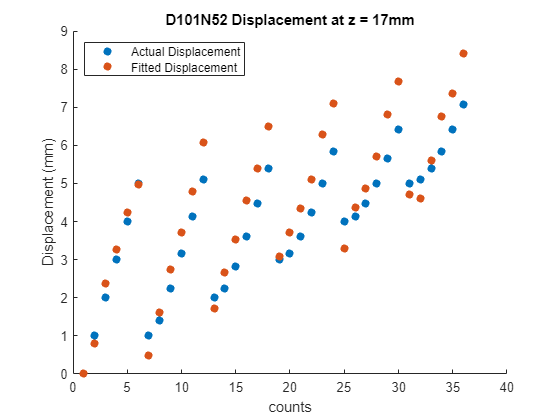


scatter(1:length(zi2), zi2, 'filled')
hold on;
scatter(1:length(testx), testx, 'filled')
title('D101N52 Displacement at z = 17mm')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

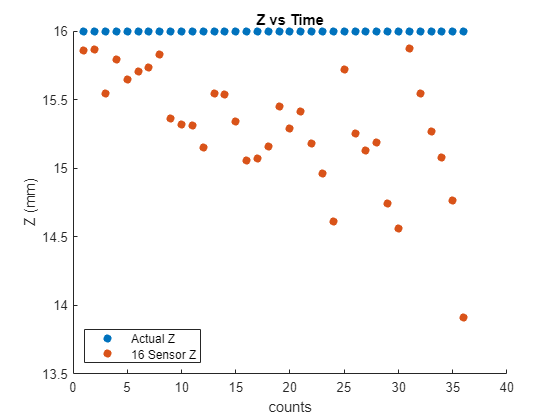

scatter(1:length(multiloc),loc(:,3), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([31,33])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

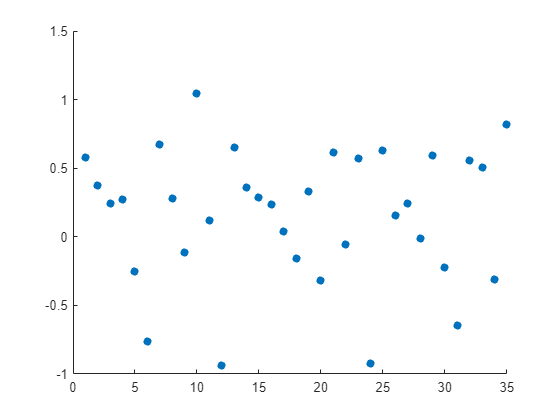

test = diff(multiloc(:,1));
scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -22]

multidisp =       -1.6575       -1.076      -6.1388
      -1.0824     -0.50515      -6.1352
     -0.70526       1.0676       -6.458
     -0.46512        1.967      -6.2078
     -0.19319       2.8812      -6.3568
     -0.44724        3.748      -6.2941
      -1.2095     -0.91121      -6.2686
     -0.53347     0.063234      -6.1685
     -0.25097       1.2124      -6.6379
     -0.36835       2.3682       -6.683


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =         6.449
       6.2504
       6.5835
       6.5286
       6.9819
       7.3392
       6.4489
       6.1919
       6.7523
       7.0998



disp = [4.98 5.08 5.35 5.78 6.34 7.01 5.08 5.18 5.45 5.9 6.46 7.12 5.37 5.47 5.74 6.13 6.66 7.3 5.81 5.91 6.15 6.55 7.05 7.67 6.41 6.47 6.70 7.05 7.55 8.11 7.06 7.13 7.34 7.67 8.1 8.65]'

disp =          4.98
         5.08
         5.35
         5.78
         6.34
         7.01
         5.08
         5.18
         5.45
          5.9


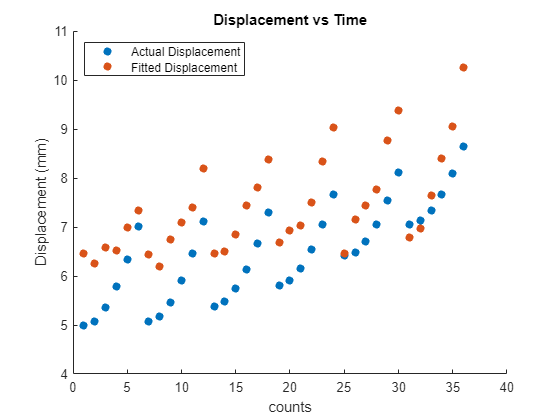


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end